fileS1='05-07-2016_02_00_02_top';
fileS2='05-07-2016_02_00_54_top';
tempS1=imagedata(fileS1);
tempS2=imagedata(fileS2);

addpath('../Library');

%Define the physical constant
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
warning('off','all');
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = VirialUnitarity( );
filefolder_Unitary='/Users/Zhenjie/Data/2016-05-06/';

filefolder_Polarized='/Users/Zhenjie/Data/2016-05-06/';

[~,~,~,VsortS1,~,~,~,EFS1]=EOS_Online( [filefolder_Polarized,fileS1,'.fits'] ,'ROI1',[157,50,390,450],...
    'ROI2',[157,220,390,280],'ShowOutline',0,'TailRange',[90,410],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',0.9,'kmin',0.15,...
    'Fudge',1.6,'BGSubtraction',0,'IfFitExpTail',1,'Nsat',130,'ShowPlot',0,'CutOff',inf);


[~,~,~,VsortS2,~,~,~,EFS2]=EOS_Online( [filefolder_Polarized,fileS2,'.fits'] ,'ROI1',[157,50,390,450],...
    'ROI2',[157,230,390,267],'ShowOutline',0,'TailRange',[120,320],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',0.9,'kmin',0.15,...
    'Fudge',1.6,'BGSubtraction',0,'IfFitExpTail',1,'Nsat',130,'ShowPlot',0,'CutOff',inf);



VsortS1=VsortS1/hh;EFS1=EFS1/hh;
VsortS2=VsortS2/hh;EFS2=EFS2/hh;

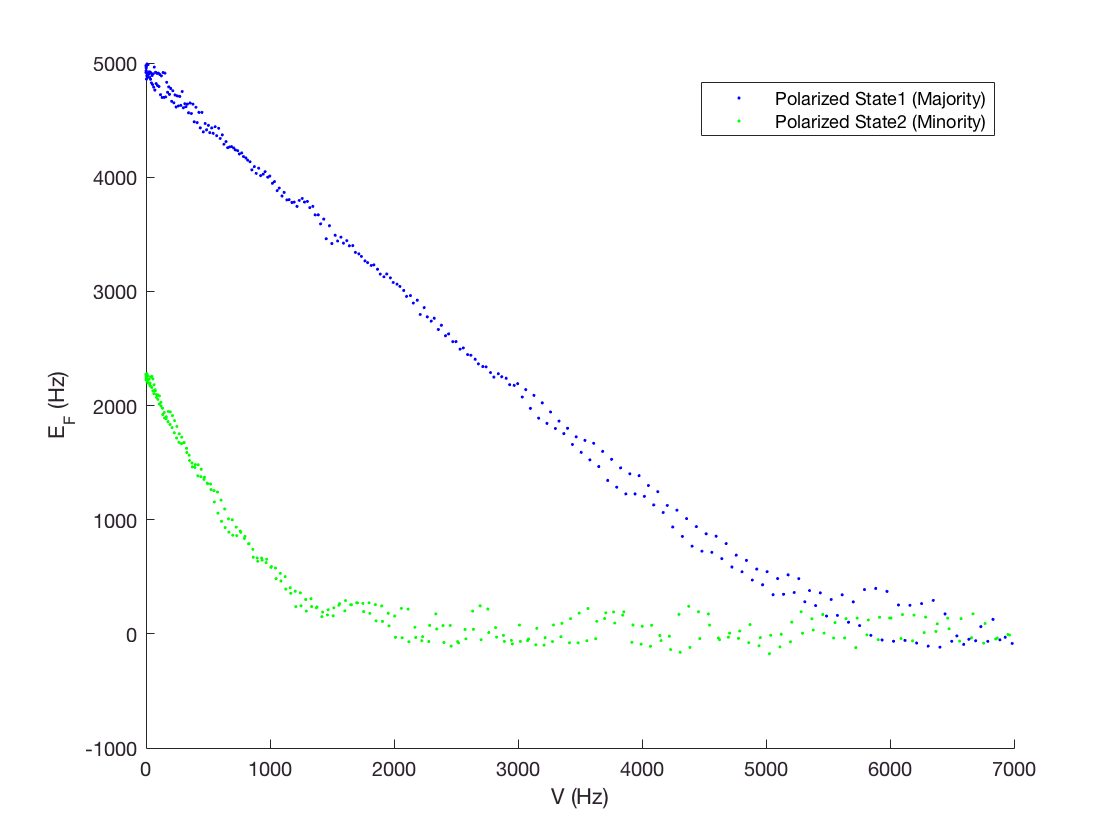

scatter(VsortS1,EFS1,'b.','DisplayName','Polarized State1 (Majority)');
hold on
scatter(VsortS2,EFS2,'g.','DisplayName','Polarized State2 (Minority)');
xlim([0,7000])
legend('Show')
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

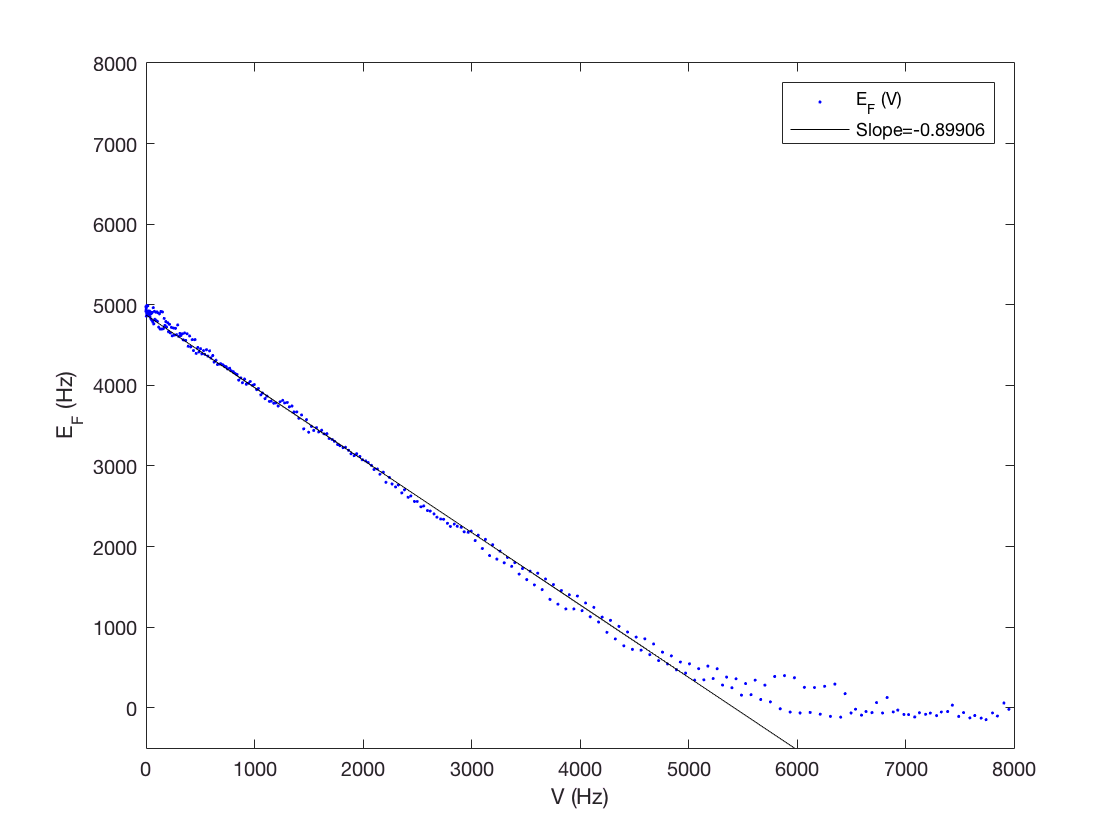

FitRangePolarized1=1000;
FitRangePolarized2=2000;
Mark1=(VsortS1<FitRangePolarized2);
Mark2=(VsortS1>FitRangePolarized1);
Mark=Mark1 & Mark2;
EFfitS1=EFS1(Mark);
VfitS1=VsortS1(Mark);

pS1=polyfit(VfitS1,EFfitS1,1);
EFlineS1=polyval(pS1,VsortS1);
plot(VsortS1,EFS1,'b.','DisplayName','E_F (V)');
xlim([0,8000]);ylim([-500,8000]);
hold on
plot(VsortS1,EFlineS1,'k','DisplayName',['Slope=',num2str(pS1(1))]);
xlabel('V (Hz)');ylabel('E_F (Hz)');
legend('show');
hold off

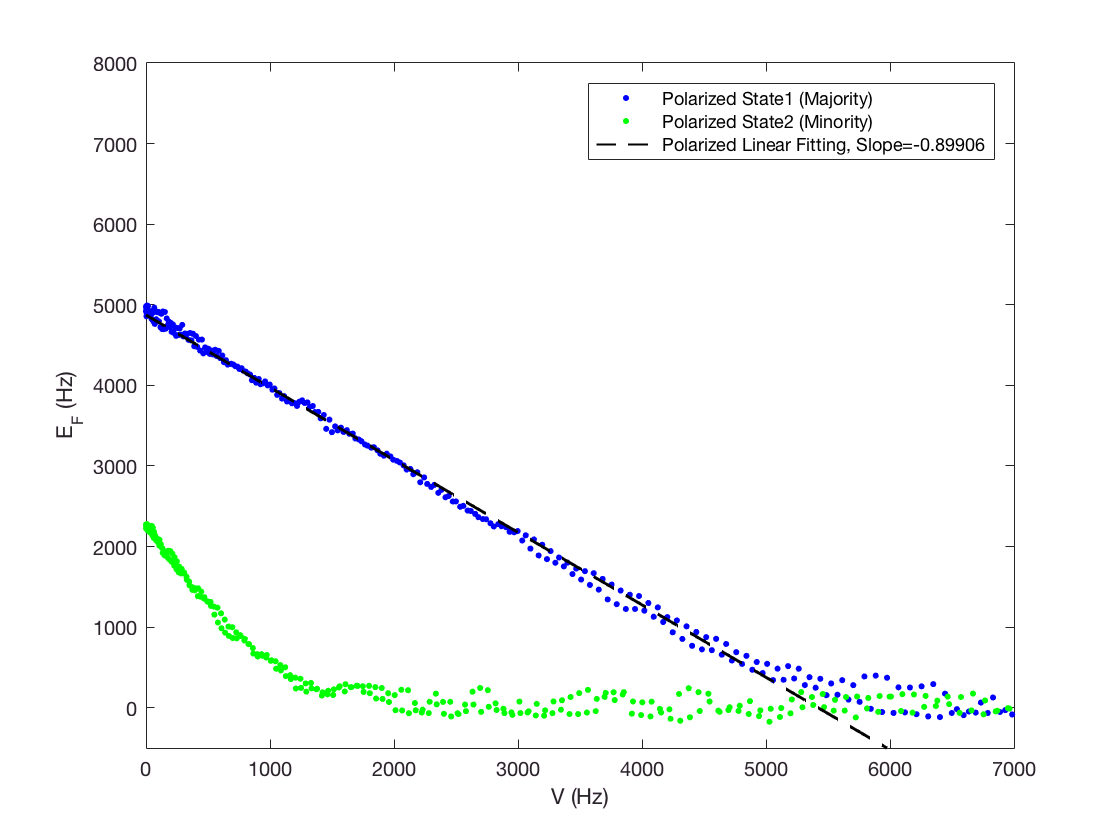

plot(VsortS1,EFS1,'b.','DisplayName','Polarized State1 (Majority)','MarkerSize',15);
hold on
plot(VsortS2,EFS2,'g.','DisplayName','Polarized State2 (Minority)','MarkerSize',15);
xlim([0,7000]);
plot(VsortS1,EFlineS1,'k--','DisplayName',['Polarized Linear Fitting, Slope=',num2str(pS1(1))],'LineWidth',1);
legend('Show')
ylim([-500,8000]);
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

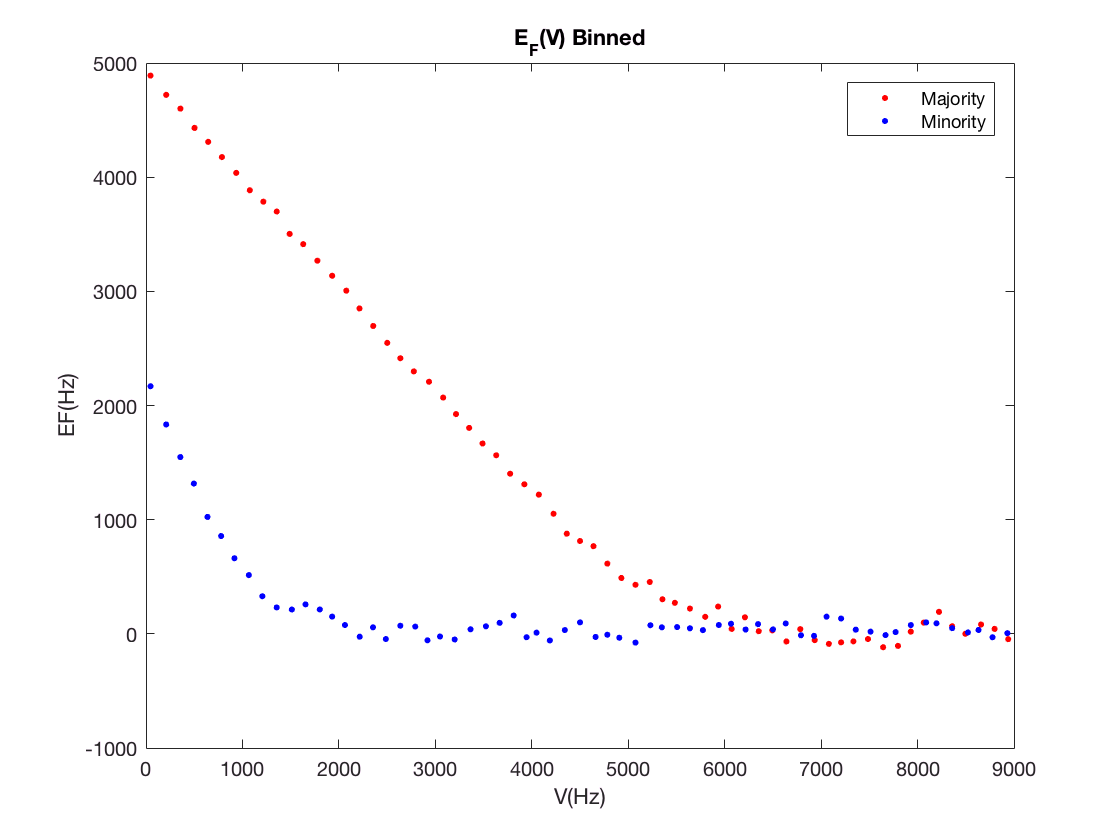

Ngrid=70;
Vgrid=linspace(0,10000,Ngrid+1);
[V1mean,EFS1mean,V1err,EF1err]=BinGrid( VsortS1,EFS1,Vgrid,2);
[V2mean,EFS2mean,V2err,EF2err]=BinGrid( VsortS2,EFS2,Vgrid,2);

plot(V1mean,EFS1mean,'r.','MarkerSize',15,'DisplayName','Majority')
hold on
plot(V2mean,EFS2mean,'b.','MarkerSize',15,'DisplayName','Minority')
xlabel('V(Hz)');ylabel('EF(Hz)')
title('E_F(V) Binned');
legend('show')
xlim([0,9000])
hold off

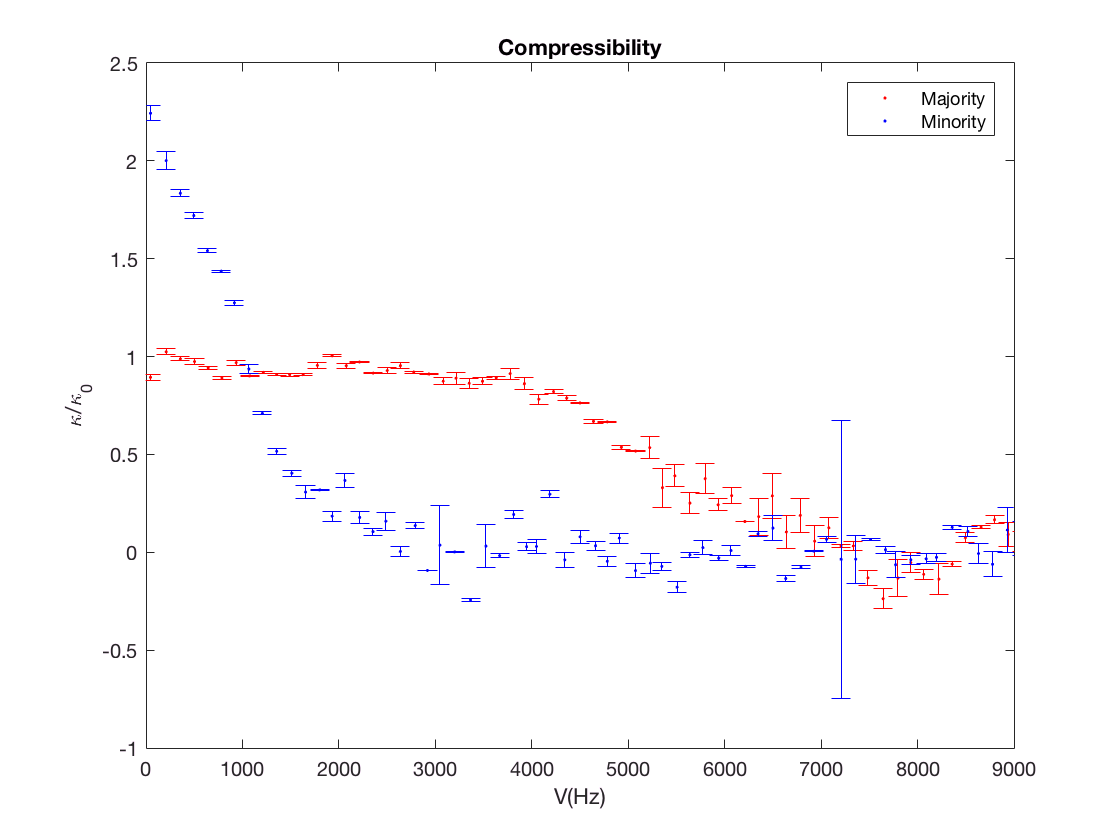




[KappaT1,KappaTerr1]=FiniteD( V1mean,V1err,EFS1mean,EF1err,4 );
KappaT1=-KappaT1;
[KappaT2,KappaTerr2]=FiniteD( V2mean,V2err,EFS2mean,EF2err,3 );
KappaT2=-KappaT2;
%% Get the Kappa vs V
errorbar(V1mean,KappaT1,KappaTerr1,'r.','DisplayName','Majority')
hold on
errorbar(V2mean,KappaT2,KappaTerr2,'b.','DisplayName','Minority')
legend('show')
xlim([0,9000]);%ylim([-0.2,1.4])
xlabel('V(Hz)');ylabel('\kappa/\kappa_0')
title('Compressibility');
hold off

Re-construct the n2/n1;

EFS2p=interp1(V2mean,EFS2mean,V1mean,'spline','extrap');
Imbalance=real((EFS2p./EFS1mean).^(3/2));
Imbalance(V2mean>3000)=0;
mask= (V1mean<2000) & (V1mean>1000);
f = fit(V1mean(mask)',Imbalance(mask)','exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.2616  (-0.2082, 0.7315)
       b =   -0.001765  (-0.003167, -0.0003636)

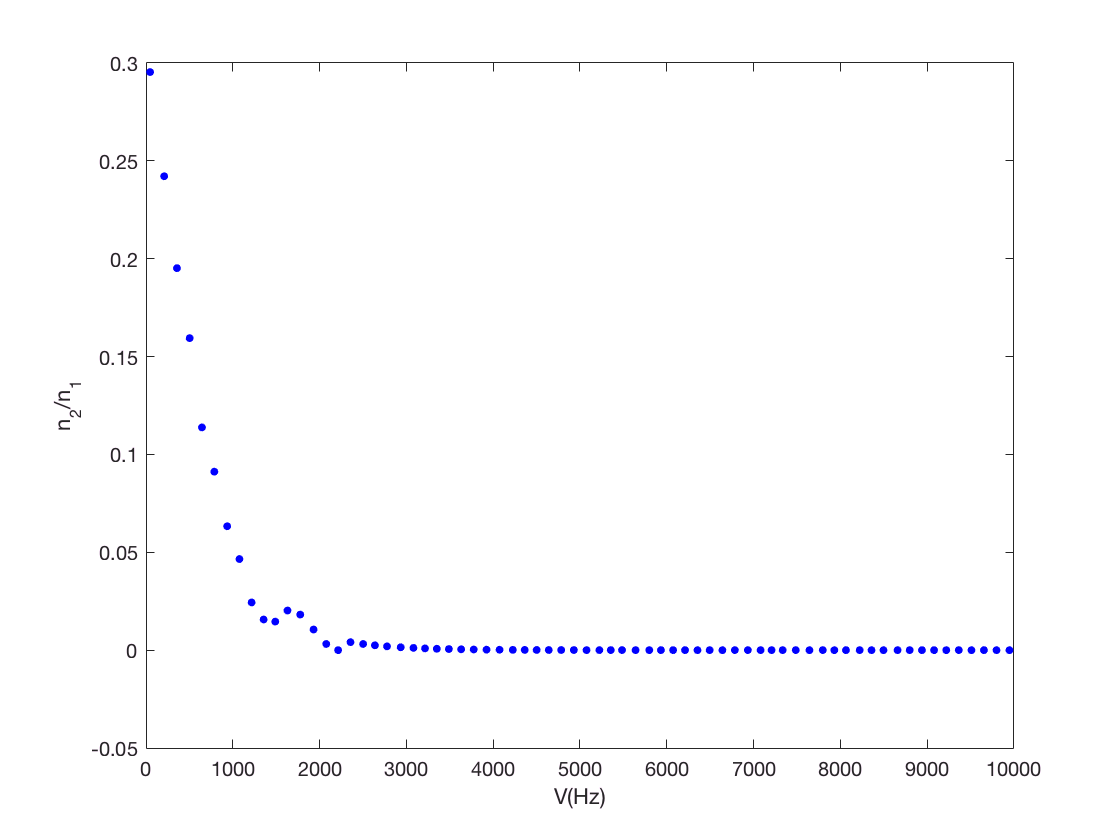

Imbalance(V1mean>2300)=f(V1mean(V2mean>2300));
plot(V1mean,Imbalance,'b.','Markersize',20);
ylim([-0.05,0.3]);
ylabel('n_2/n_1');xlabel('V(Hz)')

Plot kappaTilde1 vs n2/n1

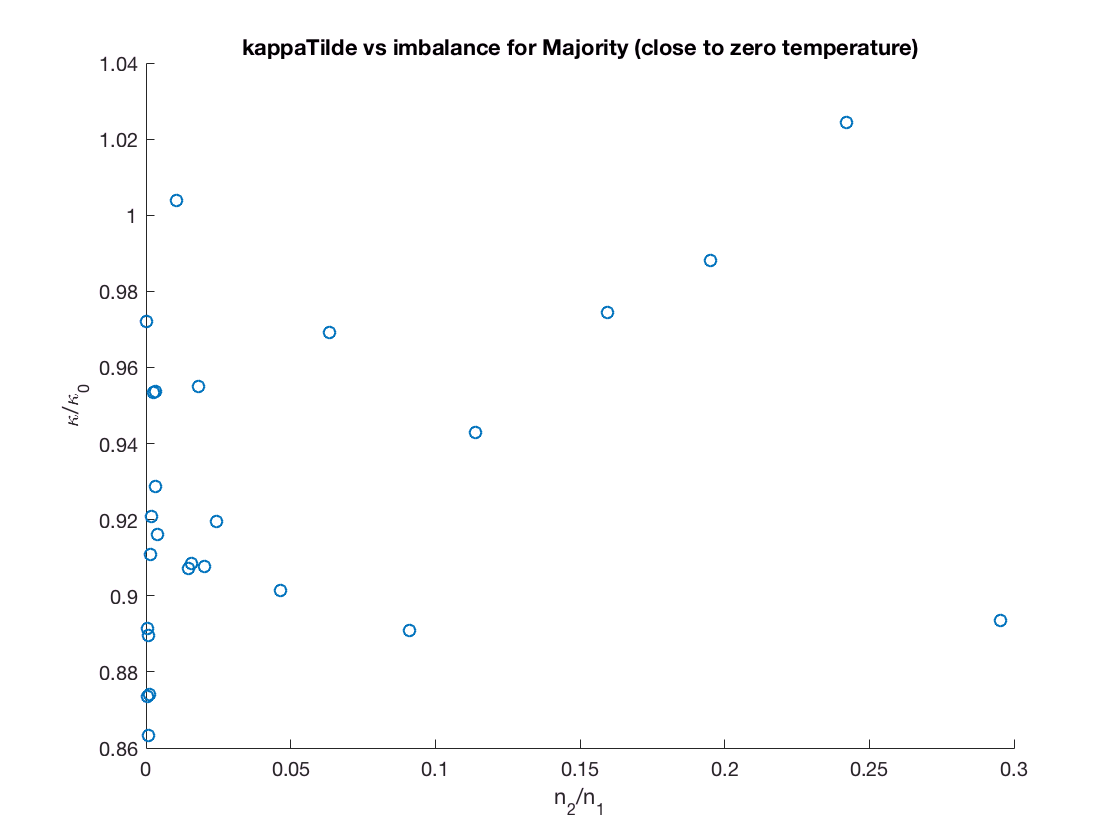

scatter(Imbalance(V1mean<3700),KappaT1(V1mean<3700));
ylabel('\kappa/\kappa_0');xlabel('n_2/n_1');
title('kappaTilde vs imbalance for Majority (close to zero temperature)');

Plot kappaTilde1 vs n2/n1

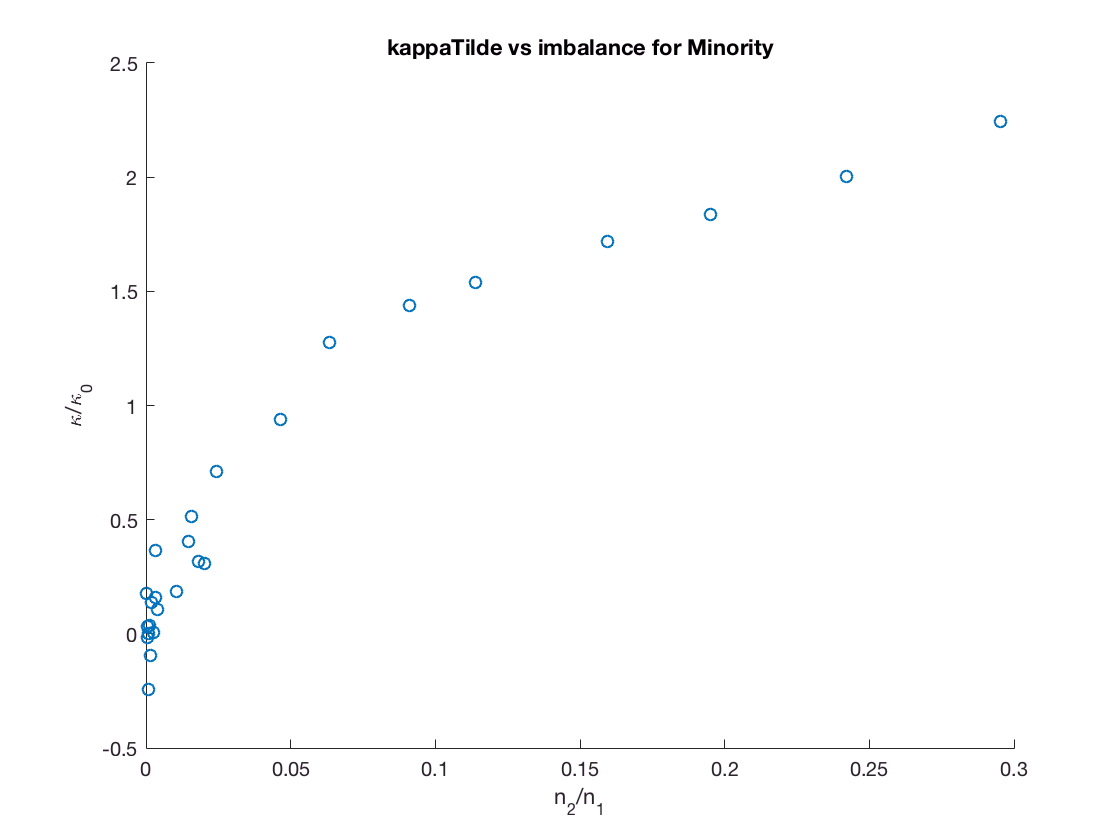

scatter(Imbalance(V1mean<3700),KappaT2(V1mean<3700));
ylabel('\kappa/\kappa_0');xlabel('n_2/n_1');
title('kappaTilde vs imbalance for Minority');

Introduce the effective potential for the minority:

V=A*EF_maj+V; A~-0.6

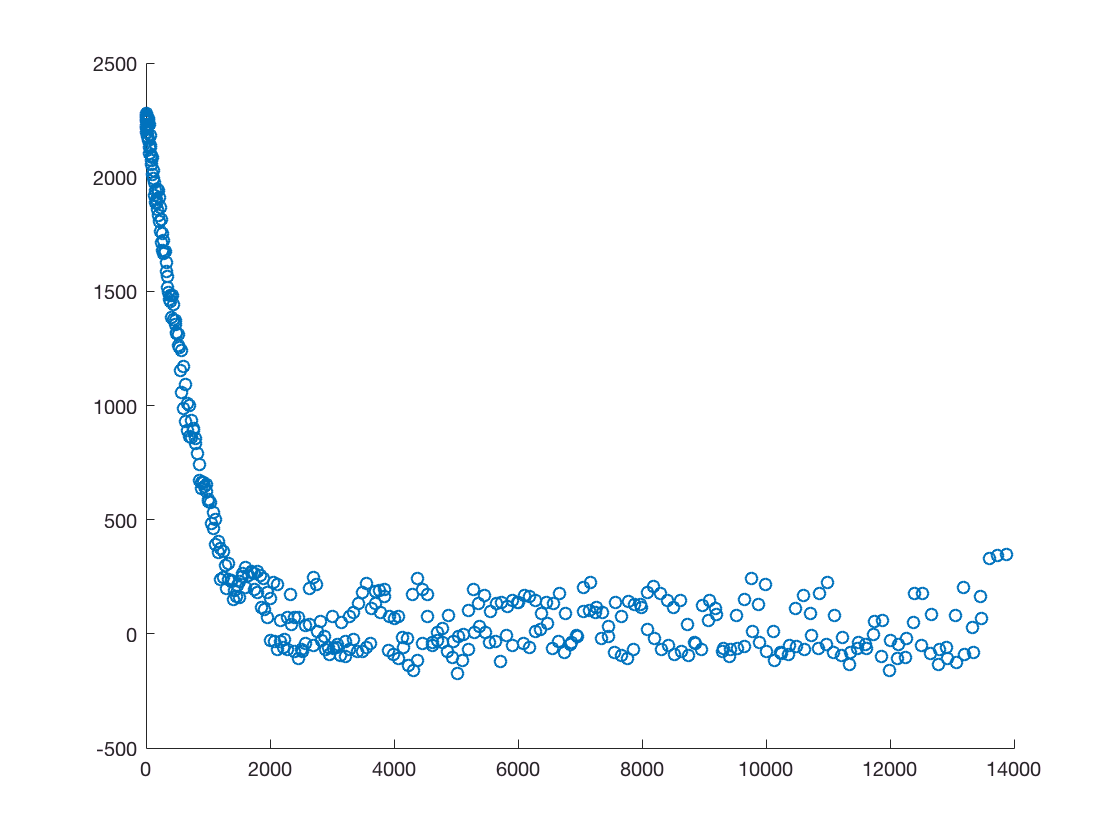

scatter(VsortS2,EFS2)

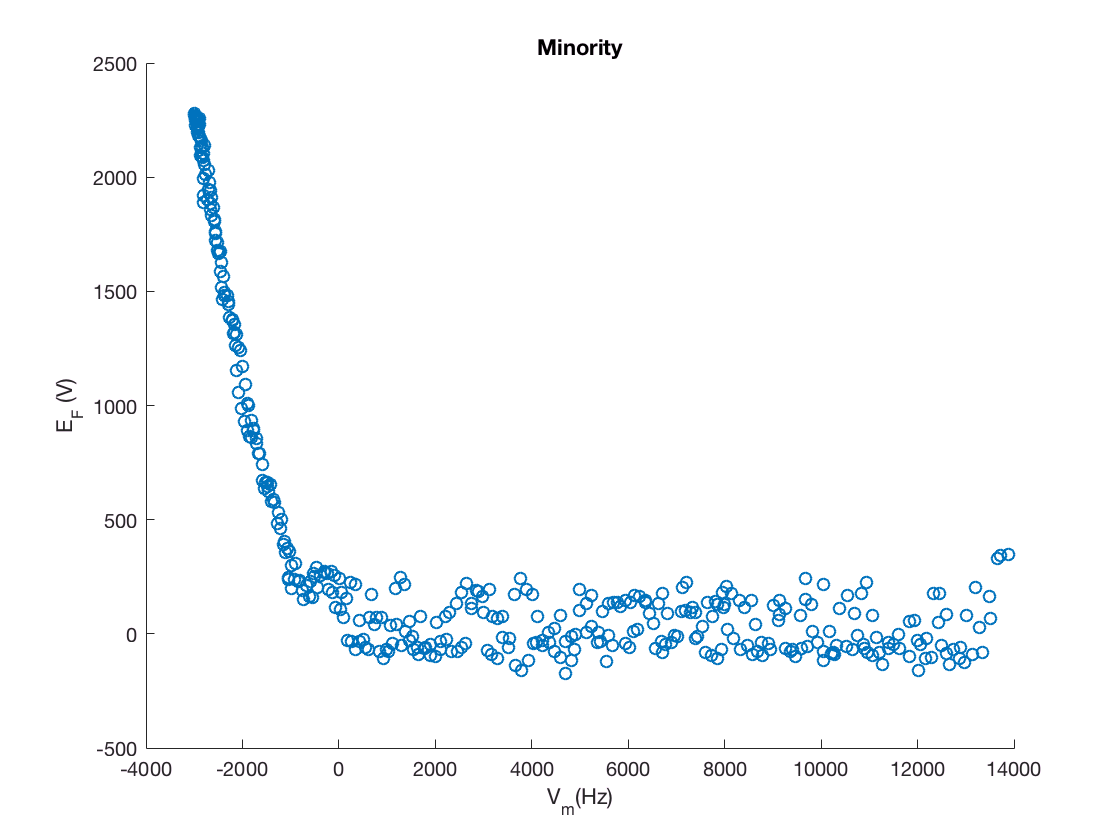


EFS1p=interp1(VsortS2,EFS1,VsortS2,'spline','extrap');

Vprime=-0.6*EFS1+VsortS2;

scatter(Vprime,EFS2);
xlabel('V_m(Hz)');ylabel('E_F (V)');
title('Minority');

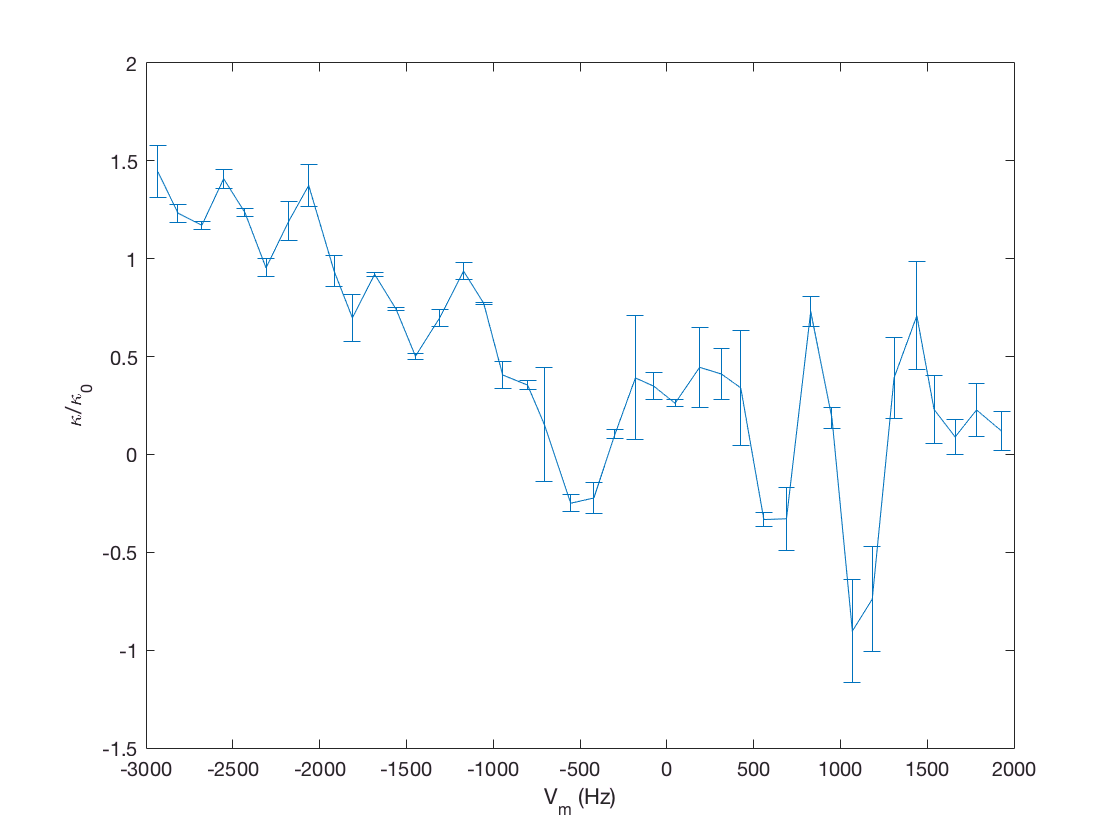


Vgrid=linspace(min(Vprime),2000,41);
[VprimeMean,EFS2Mean,VprimeErr,EF2Err]=BinGrid( Vprime,EFS2,Vgrid,2);
[KappaT2,KappaTerr2]=FiniteD( VprimeMean,VprimeErr,EFS2Mean,EF2Err,1 );
KappaT2=-KappaT2;

errorbar(VprimeMean,KappaT2,KappaTerr2)
xlabel('V_m (Hz)');ylabel('\kappa/\kappa_0');